# LG FULL

# Parameters

53 original

+1 for LD

+11 for full

The params are varied from table 1! Check fig 8.

%% Parameters, 65 in total
p = struct();
p.k_1 = 0.8;
p.k_2 = 0.4;
p.k_3 = 0.8;
p.k_4 = 0.4;
p.k_5 = 0.8;
p.k_6 = 0.4;
p.k_7 = 1;
p.k_8 = 0.2;
p.K_AP = 0.6;
p.K_AC = 0.6;
p.K_IB = 2.2;
p.k_dmb = 0.02;
p.k_dmc = 0.02;
p.k_dmp = 0.02;
p.k_dn = 0.02;
p.k_dnc = 0.02;
p.K_d = 0.3;
p.K_dp = 0.1;
p.K_p = 1.006;
p.K_mB = 0.4;
p.K_mC = 0.4;
p.K_mP = 0.3;
p.k_sB = 0.32;
p.k_sC = 3.2;
p.k_sP = 1.2;
p.m = 2;
p.n = 2;
p.V_1B = 1.4;
p.V_1C = 1.2;
p.V_1P = 9.6;
p.V_1PC = 2.4;
p.V_2B = 0.2;
p.V_2C = 0.2;
p.V_2P = 0.6;
p.V_2PC = 0.2;
p.V_3B = 1.4;
p.V_3PC = 2.4;
p.V_4B = 0.4;
p.V_4PC = 0.2;
p.V_phos = 0.4;
p.v_dBC = 3;
p.v_dBN = 3;
p.v_dCC = 1.4;
p.v_dIN = 1.6;
p.v_dPC = 3.4;
p.v_dPCC = 1.4;
p.v_dPCN = 1.4;
p.v_mB = 1.3;
p.v_mC = 2;
p.v_mP = 2.2;
p.v_sB = 1.8;
p.v_sC = 2.2;
p.v_sP = 2.4;
p.v_sPmax = 3; % for light

% for full model
p.v_sR = 1.6;
p.K_AR = 0.6;
p.v_mR = 1.6;
p.K_mR = 0.4;
p.k_dmr = 0.02;
p.k_sR = 1.7;
p.k_9 = 0.8;
p.k_10 = 0.4;
p.v_dRC = 4.4;
p.v_dRN = 0.8;
p.h = 2;

p_fields = {'k_1', 'k_2', 'k_3', 'k_4', 'k_5', 'k_6', 'k_7', 'k_8', ...
              'K_AP', 'K_AC', 'K_IB', 'k_dmb', 'k_dmc', 'k_dmp', 'k_dn', 'k_dnc', ...
              'K_d', 'K_dp', 'K_p', 'K_mB', 'K_mC', 'K_mP', 'k_sB', 'k_sC', ...
              'k_sP', 'm', 'n', 'V_1B', 'V_1C', 'V_1P', 'V_1PC', 'V_2B', ...
              'V_2C', 'V_2P', 'V_2PC', 'V_3B', 'V_3PC', 'V_4B', 'V_4PC', 'V_phos', ...
              'v_dBC', 'v_dBN', 'v_dCC', 'v_dIN', 'v_dPC', 'v_dPCC', 'v_dPCN', ...
              'v_mB', 'v_mC', 'v_mP', 'v_sB', 'v_sC', 'v_sP', 'v_sPmax', 'v_sR', ...
              'K_AR', 'v_mR', 'K_mR', 'k_dmr', 'k_sR', 'k_9', 'k_10', 'v_dRC', ...
              'v_dRN', 'h'};

p_array = zeros(length(p_fields), 1);

for i = 1:length(p_fields)
    p_array(i) = p.(p_fields{i});
end

# y: 19 vars

y = struct();
y.M_P = 3.0;
y.M_C = 3.7;
y.M_B = 5.5;

y.P_C = 0;
y.C_C = 0;
y.P_CP = 0;
y.C_CP = 0;

y.PC_C = 0;
y.PC_N = 0;
y.PC_CP = 0;
y.PC_NP = 0;

y.B_C = 0;
y.B_CP = 0;
y.B_N = 0;
y.B_NP = 0;

y.I_N = 0;

y.M_R = 2.0;
y.R_C = 0;
y.R_N = 0;

y_fields = {'M_P', 'M_C', 'M_B', 'P_C', 'C_C', 'P_CP', 'C_CP', ...
            'PC_C', 'PC_N', 'PC_CP', 'PC_NP', 'B_C', 'B_CP', 'B_N', 'B_NP', 'I_N', ...
            'M_R', 'R_C', 'R_N'};

y_array = zeros(length(y_fields), 1);

for i = 1:length(y_fields)
    y_array(i) = y.(y_fields{i});
end

# Options

tspan = [0 480];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);

# DD模拟

[t1, y1] = ode45(@LG_full, tspan, y_array, options, p_array);

# 绘图，最后72小时（3天）

P_tot, C_tot, B_tot

delay = 72

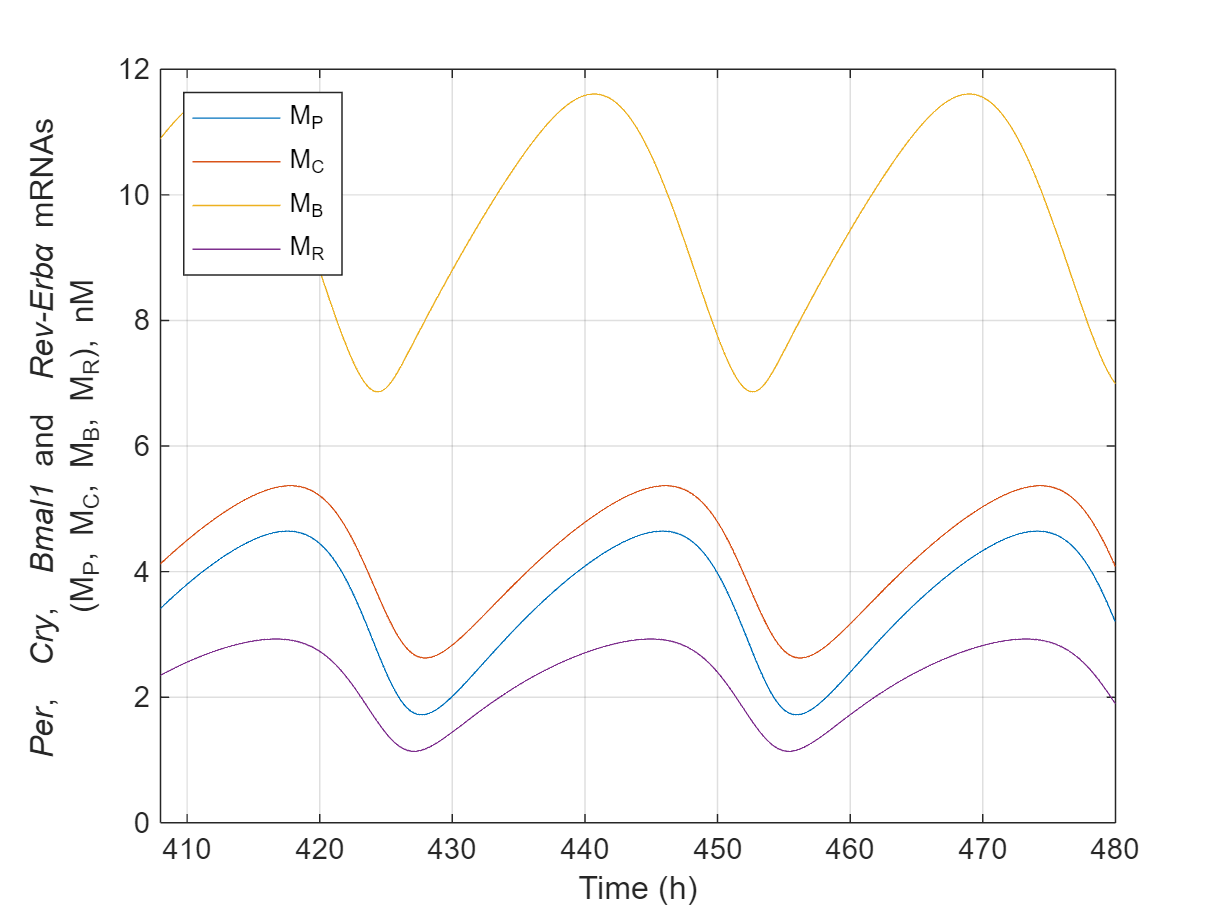

delay = 72;

M_P = y1(:, 1);
M_C = y1(:, 2);
M_B = y1(:, 3);
M_R = y1(:, 17);

figure;
plot(t1, M_P, t1, M_C, t1, M_B, t1, M_R);
xlabel('Time (h)');
ylabel({'{\it Per}, {\it Cry}, {\it Bmal1} and {\it Rev-Erb\alpha} mRNAs', '(M_P, M_C, M_B, M_R), nM'});
legend('M_P', 'M_C', 'M_B', 'M_R', 'Location', 'northwest');
xlim([t1(end)-delay, t1(end)]);
grid on;

# 使用峰值测量DD Per mRNA周期

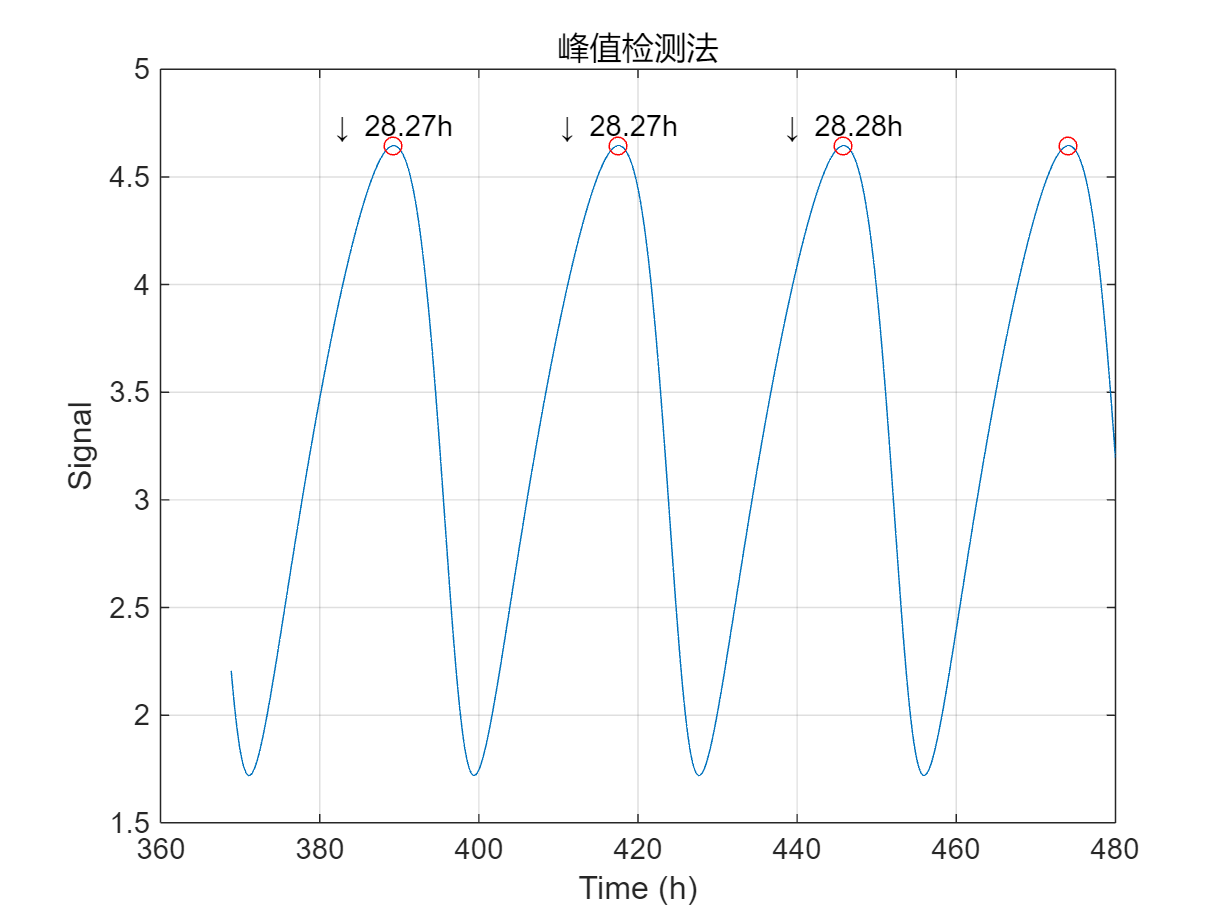

峰值检测结果：平均振荡周期为 28.27 小时


t_signal = t1;
signal = y1(:,1);

period_peak(t_signal, signal);

# LD模拟

[t2, y2] = ode45(@LG_full_light, tspan, y_array, options, p_array);

# 绘图

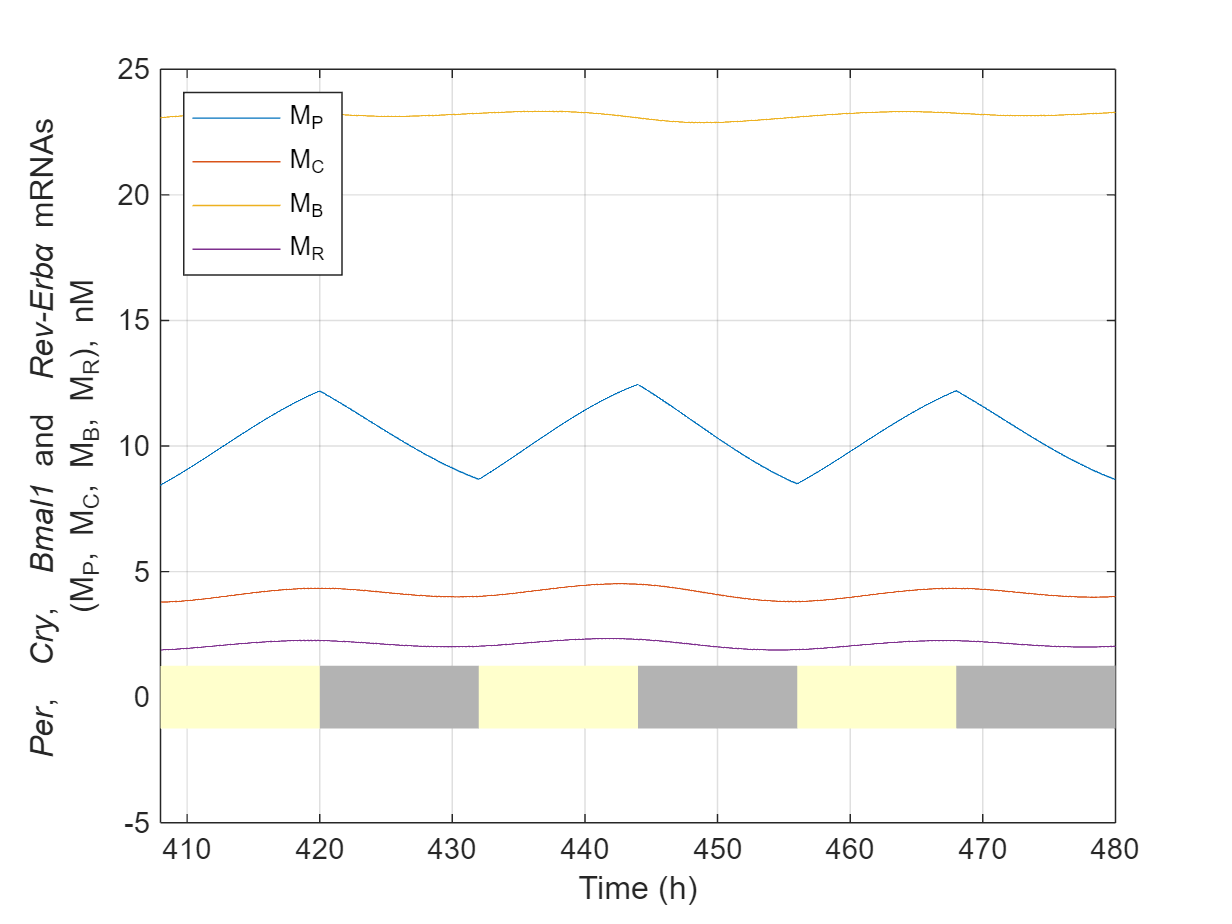

M_P = y2(:, 1);
M_C = y2(:, 2);
M_B = y2(:, 3);
M_R = y2(:, 17);

figure;
plot(t2, M_P, t2, M_C, t2, M_B, t2, M_R);
xlabel('Time (h)');
ylabel({'{\it Per}, {\it Cry}, {\it Bmal1} and {\it Rev-Erb\alpha} mRNAs', '(M_P, M_C, M_B, M_R), nM'});
legend('M_P', 'M_C', 'M_B', 'M_R', 'Location', 'northwest');
xlim([t2(end)-delay, t2(end)]);
grid on;

% Get current axis limits
ax = gca;
ylims = ylim;
ypos = ylims(1) - 0.05*(ylims(2)-ylims(1)); % Position slightly below the plot

% Add light-dark indicators
start_time = t2(end)-delay;
end_time = t2(end);
for t = ceil(start_time/24)*24:24:end_time
    % Light phase (white or light yellow rectangle)
    rectangle('Position', [t, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [1 1 0.8], 'EdgeColor', 'none');
    % Dark phase (gray rectangle)
    rectangle('Position', [t+12, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none');
end

# 测量LD周期

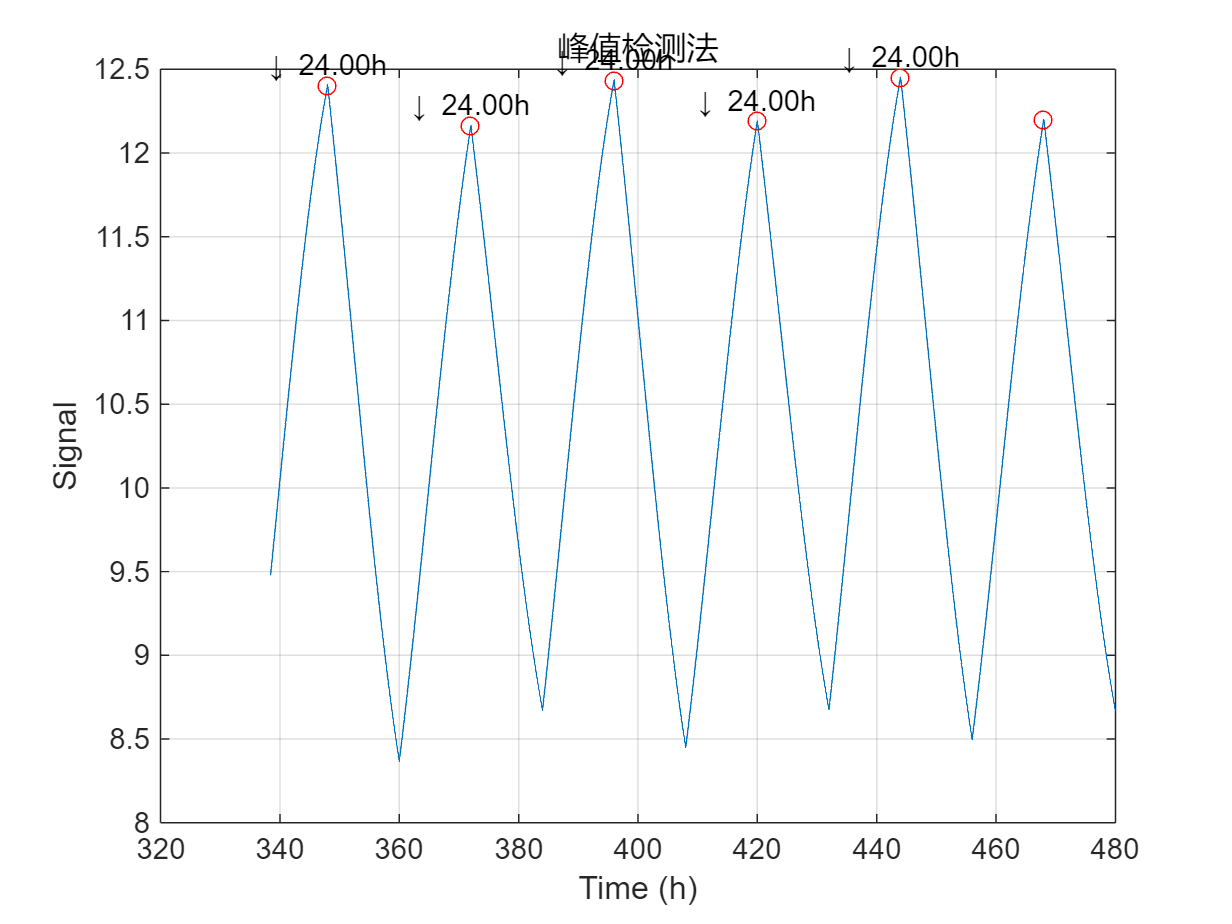

峰值检测结果：平均振荡周期为 24.00 小时


t_signal = t2;
signal = y2(:,1);

period_peak(t_signal, signal);